# Magnetic Field of a Ring Filament

This script demonstrates magnetic field of ring shaped filament in vacuum.

#### Create Circle

radius = 1

radius = 1

center = [0 0 0]

center =      0     0     0


r = Ring(radius, center);

figure;
plot3(r);

#### Pick an Observation Point

obs = [0 0 0]

obs =      0     0     0


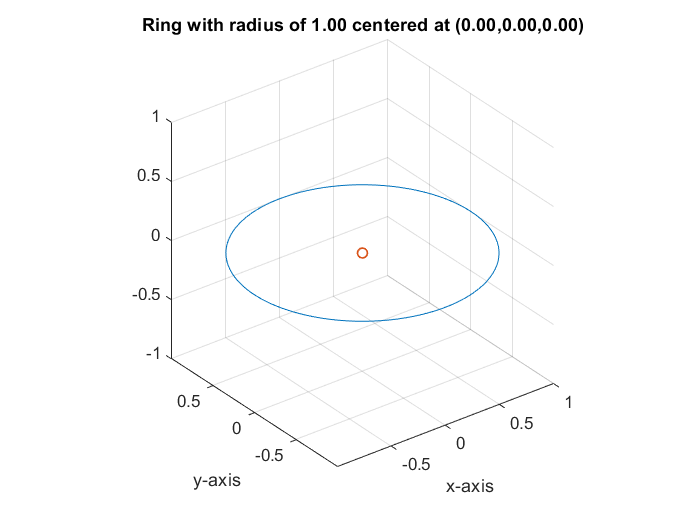


hold on;
scatter3(obs(1), obs(2), obs(3), 'LineWidth', 1);
axis equal;
hold off;

#### Calculate Magnetic Field Numerically

sample_count = 1000

sample_count = 1000


% Calculate magnetic field with specified sample count
numeric = r.observe(obs, sample_count);

#### Calculate Magnetic Field Theorically

a = radius;
rho = sqrt((obs(1)-center(1))^2+(obs(2)-center(2))^2);
z = abs(obs(3)-center(3));

theoretical = zeros(1,3);
if rho == 0
    if z == 0
        theoretical(3) = constants.mu_zero/2/a;
    else
        theoretical(3) = constants.mu_zero/2*a^2/sqrt((a^2+z^2)^3);
    end
else
    theoretical = ringB(a,rho,z);
end

#### Report Error and Configuration

disp(r)

Ring(radius=1.00, center=(0.00,0.00,0.00))


fprintf("Magnetic field observed at (%0.2f,%0.2f,%0.2f):", obs(1), obs(2), obs(3));

Magnetic field observed at (0.00,0.00,0.00):

fprintf(" -> Numerically: (%E,%E,%E) T", numeric(1), numeric(2), numeric(3));

 -> Numerically: (0.000000E+00,0.000000E+00,6.284959E-07) T

fprintf(" -> Theoretically: (%E,%E,%E) T", ...
    theoretical(1), theoretical(2), theoretical(3));

 -> Theoretically: (0.000000E+00,0.000000E+00,6.285000E-07) T

n = abs(numeric);
t = abs(theoretical);
error = abs(numeric - theoretical) / theoretical * 100;
fprintf("Percentage error is %0.2f.", error);

Percentage error is 0.00.